# **Final Group Project **- Allie Hearn and Rex Aledia

# *Coupled flow and saline intrusion in a coastal aquifer (Bakker 2016)*

## Introduction

        Ground water makes up about 30% of the world’s freshwater. Since most of the remaining 70% is frozen, groundwater is the primary source of drinking water for many$\ldotp^1$ It is relied on by one-third of the United States population$\ldotp^3$ Groundwater is accessed by drilling wells below the water table into layers of permeable rock, called aquifers. This water source is not infinite, however. High rates of water pumping can deplete the aquifer and overtime, lower the water table. This leads to wells running dry or,  in coastal regions, being replaced with saltwater$\ldotp^2$

	When the freshwater in an aquifer is replaced over time by saltwater from the ocean, it is called saltwater intrusion. Saltwater intrusion is a major issue for coastal regions that rely on groundwater for drinking water. Pumping freshwater from aquifers directly leads to saltwater intrusion, as the ocean moves inland in order to replace the freshwater that is being taken. Increasing the rate of pumping also increases the rate at which saltwater intrusion happens$\ldotp^4$ For a long time, this has been a difficult problem to optimize. It is not just a challenge for humans. Saltwater intrusion can have an impact on the environment as well by damaging ecosystems reliant on having freshwater available$\ldotp^2$ 

	For over 75 years now, scientists have been working on models to help us understand factors that impact saltwater intrusion and the rate at which it happens$\ldotp^1$ Models can help us make better choices in regard to water pumping by predicting the impacts of different water resource decisions. Making good decisions will help us to both protect the environment and to keep coastal aquifers as a resource to us as drinking water$\ldotp^2$

        In order to more easily create models of saltwater intrusion, scientists have come up with many different approximations to simplify the equations involved.  The model presented here combines three of these different approximations. The first is the Dupuit approximation, developed in the late 1800s. This approximation assumes that groundwater flow is horizontal in order to neglect the resistance to vertical flow within the aquifer. With this assumption, the water table is flat and groundwater is hydrostatic$\ldotp^5$ 

	This model also makes use of the Boussinesq approximation which ignores density in order to simplify flow equations$\ldotp^6$ In order to use this approximation, one must assume that the density difference between freshwater and saltwater is relatively small. The third approximation assumes that the freshwater and salt water are immiscible, meaning they do not mix together. This approximation ignores diffusion and dispersion between the two liquids, In order for this approximation to be reasonable, the time period over which the model is run must be relatively short. 

In addition to these major ones, a couple minor assumptions are made. It is assumed that the viscosity of both liquids are equal and that the aquifer is isotropic. 

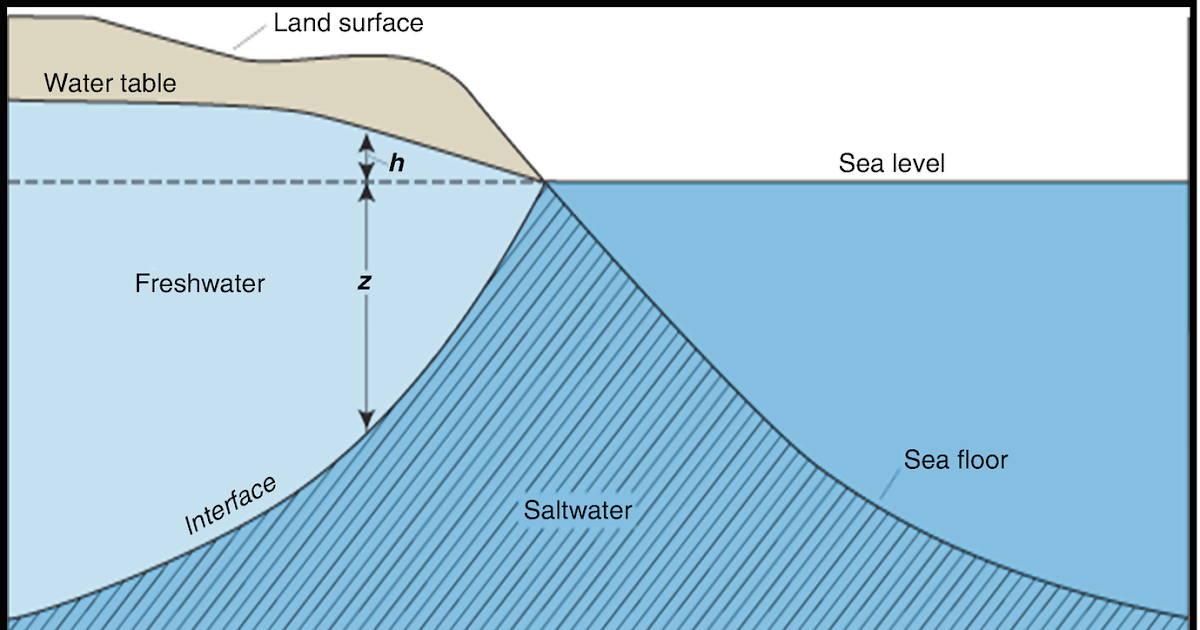

*Figure I: Diagram of the freshwater-saltwater interface with parameters h and z. *

## Derivation of Equations

        This model consists of two equations. The first equation defines one-dimensional interface flow in a single aquifer. The derivation of this equation starts with Darcy’s law, which describes the flow of a fluid through a porous medium$\ldotp^7$


$$q_x =-k\frac{\partial \phi }{\partial x}$$


$q_x$ represents the discharge in the x direction, k is the hydraulic conductivity of freshwater, and x shows how the freshwater head, 𝜙, changes in the x direction. The freshwater head is the elevation relative to a baseline point that freshwater rises in a well drilled into an aquifer. The position of the freshwater head is directly related to the position of the freshwater-saltwater interface. The freshwater head can be defined with a piecewise function using the Dupuit approximation. 


$$\phi =h,\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;z\ge \zeta$$



$$\phi =h+v_s \left(\zeta -z\right),\;\;z\le \zeta$$


‘h’ is the head in the freshwater zone which is typically the height difference between sealevel and the water table, $v_s$ is the dimensionless density difference defined by $v_s =\frac{\left(\rho_s -\rho_f \right)}{\rho_f }$, and $\zeta$ is the vertical elevation of the freshwater-saltwater interface relative to sealevel. 

Combining the equation from Darcy’s law and the definition of the freshwater head, we get


$$q_x =-k\frac{\partial h}{\partial x},\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;z\ge \zeta$$



$$q_x =-k\frac{\partial h}{\partial x}-k\frac{\partial \zeta }{\partial x},\;\;z\le \zeta$$


Next, the discharge vector is defined. The discharge vector is the integral of qx with respect to z from the bottom of the saturated aquifer to the top. The result is


$$Q_x =-k\left(z_t -z_b \right)\frac{\partial h}{\partial x}-kv_s \left(z_t -z_b \right)\frac{\partial \zeta }{\partial x}$$


Substituting in the definition of transmissivity ($T=k\left(z_t -z_b \right)$) and 'salt' transmissivity ($\tau =kv_s \left(z_t -z_b \right)$), the equation becomes


$$Q_x =-T\frac{\partial h}{\partial x}-\tau \frac{\partial \zeta }{\partial x}$$


Applying the Boussinesq approximation, we replace the mass balance equation with a volume balance equation, introducing N, the infiltration of salwater, and S, the storage coefficient.

$\frac{\partial Q_x }{\partial x}=N-S\frac{\partial h}{\partial x}$                           (volume balance equation)

Finally, taking the derivative of the discharge vector gives the final equation for one-dimensional interface flow in a single aquifer.

$\frac{\partial }{\partial x}\left(T\frac{\partial h}{\partial x}\right)=-N+S\frac{\partial h}{\partial t}-\frac{\partial }{\partial x}\left(\tau \frac{\partial \zeta }{\partial x}\right)$                                              (1)

        The second equation of the model describes the movement of the freshwater-saltwater interface. To derive it, we start with the vertically integrated flux in the saltwater zone. Similar to above, $q_x$ is integrated with respect to z, but this time the interval is from the bottom of the aquifer to $\zeta$, the elevation of the interface.  The resulting equation with the trasmissivity definitions substituted in is


$$Q_x^s =\frac{-\tau }{v_s }\frac{\partial h}{\partial x}-\tau \frac{\partial \zeta }{\partial x}$$


Using the equation for the continuity of flow in the saltwater zone where n is the effective porosity, taking the derivative of the salt discharge yields the second equation of the model. 

$\frac{\partial }{\partial x}\left(\tau \frac{\partial \zeta }{\partial x}\right)=n\frac{\partial \zeta }{\partial t}-\frac{\partial }{\partial x}\left(\frac{\tau }{v_s }\frac{\partial h}{\partial x}\right)$                                                     (2)

## Parameters

% simulation done in paper

k = 2;          % hydraulic conductivity (m/d)
n = 0.2;        % effective porosity
S = 0;          % storage coefficient
H = 45;         % aquifer thickness (m)
zb = -45;       % bottom of aquifer (m)
zt = 0;         % top of aquifer (m)
L = 1000;       % length of cross-section (m)
W = 1;          % width of cross-section (m)
vs = 0.025;     % dimensionless density
x_ditch = 590;  % ditch position (m)
x_coastline = 0;% coastline position (m)

T = k*(zt-zb);  % transmissivity (m^2/d)
tau = vs*T;     % salt transmissivity (m^2/d)

dx = 10;        % gridspace size (m)
xi = 0;         % initial x (m)
xf = 1000;      % final x (m)
xs = xi:dx:xf;  % vector of gridspaces
nx = length(xs);% # of gridspaces

dt = 0.5;       % timestep size (yr)
ti = 0;         % initial time (yr)
tf = 500;       % final time (yr)
ts = ti:dt:tf;  % vector of timesteps
nt = length(ts);% # of timesteps

## Pre-Allocation, Initial Conditions

head_sol = zeros(nx,nt);    % solution matrix for freshwater head
zeta_sol = zeros(nx,nt);    % solution matrix for interface position

Q_IC = -0.05;               % discharge at t = 0 (m^2/d)
zeta_IC = Q_IC/k/vs;        % interface position at t = 0 (m)

zeta_sol(:,1) = zeta_IC;    % assign interface IC

## Create solver matrices, Boundary Conditions

% how to set up propagation matrices? what equation is appropriate?
%headM = spdiags();     % head matrix
%zetaM = spdiags();     % interface matrix

head_BC = 0.05;         % freshwater head at x = 0 (m)
Q_BC = 0.1;             % discharge at x = 0 (m^2/d)
zeta_BC = Q_BC/k/vs;    % interface position at x = 0 (m)

% how to assign dirichlet BCs? BC and IC mismatch

## Run model

for k = 1:nt
    %head_sol(:,k+1) = 
end

## References

- Bear, J., Cheng, A.HD. (1999). Introduction. In: Bear, J., Cheng, A.HD., Sorek, S., Ouazar, D., Herrera, I. (eds) Seawater Intrusion in Coastal Aquifers — Concepts, Methods and Practices. Theory and Applications of Transport in Porous Media, vol 14. Springer, Dordrecht. [https://doi.org/10.1007/978-94-017-2969-7_1](https://doi.org/10.1007/978-94-017-2969-7_1)

- Costall, A.R., Harris, B.D., Teo, B. *et al.* Groundwater Throughflow and Seawater Intrusion in High Quality Coastal Aquifers. *Sci Rep* **10**, 9866 (2020). [https://doi.org/10.1038/s41598-020-66516-6](https://doi.org/10.1038/s41598-020-66516-6)

- “The Quality of the Nation’s Groundwater: U.S. Geological Survey.” *The Quality of the Nation’s Groundwater | U.S. Geological Survey*, Communications and Publishing, 21 Jan. 2015, www.usgs.gov/news/featured-story/quality-nations-groundwater. 

- “Saltwater Intrusion.” *Saltwater Intrusion | U.S. Geological Survey*, Water Resources Mission Area, 2 Mar. 2019, www.usgs.gov/mission-areas/water-resources/science/saltwater-intrusion

- “Dupuit–Forchheimer Assumption.” *Wikipedia*, Wikimedia Foundation, 26 Apr. 2016, en.wikipedia.org/wiki/Dupuit%E2%80%93Forchheimer_assumption. 

- “Boussinesq Approximation (Buoyancy).” *Wikipedia*, Wikimedia Foundation, 21 Oct. 2024, en.wikipedia.org/wiki/Boussinesq_approximation_(buoyancy). 

- “Darcy’s Law.” *Wikipedia*, Wikimedia Foundation, 15 Nov. 2024, en.wikipedia.org/wiki/Darcy%27s_law. 